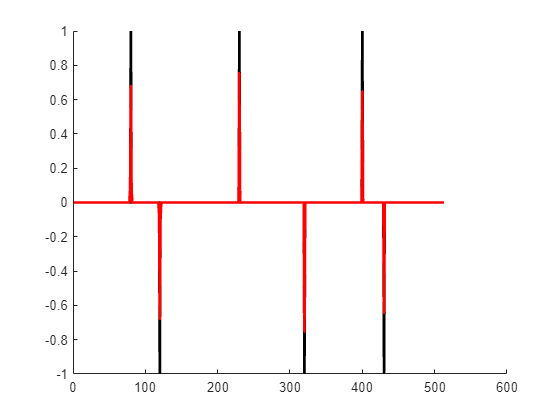

%Z_FISTA: Test adaptive step size FISTA.
% Adaptive step-size fast iterative shrinkage-thresholding algorithm and 
% sparse-spike deconvolution
%  Author(s): Ke Yan , Shulin Pan (SWPU)
%  Copyright 2018-2020
%  Revision: 1.0  Date: Dec/2018 
%  

clear;clc;close all;
n=512;
%%%%%%%%%%%%反射系数%%%%%%%%%
load('r2.mat');
%%%%%%%%%%%%子波%%%%%%%%%%%%%
load('ww03.mat');
load('w1.mat');
load('w2.mat');
load('w3.mat');
%%%%%%%%%%%合成地震记录%%%%%%%
load('s3.mat');
% randn('state',0);
% e=0.2*randn(n,1);
% e=0.05*randn(n,1);
s1=s;
% s=s+e;
%%%%%求取过完备字典的最大特征值T%%%%
www=ww0'*ww0;
[a,b]=eig(www);
eigenvalue=diag(b);
T_r=2*max(eigenvalue);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
soft =@(x,T) sign(x).*max((abs(x) - T),0);%%%软阈值求取函数%%%
z0=ones(3*n,1);
x0=ones(3*n,1);
y=ones(3*n,1);
xk=ones(3*n,1);
T0=0;
rd=0.9;
ra=2.0;

L0=10*T_r;

N=100;
lamda=3.0;
F1=norm(r,1);
f=1;U=0;
for i=1:N
    K(i)=(f+norm(xk,1))-F1;
    L=rd*L0;%%%Lipschitz常数减小
    while f>U
        t=(1+sqrt(1+4*L*T0))/(2*L);
        Tk=T0+t;
        y=(1/Tk)*(T0*x0+t*z0);
        xk=soft(y-(2/L)*ww0'*(ww0*y-s),lamda/L);
        f=norm(ww0*xk-s).^2;
        U=norm(ww0*y-s).^2+(2*ww0'*(ww0*y-s))'*(xk-y)+(L/2)*norm(xk-y).^2;
        if(f<=U)
            break;
        else
             L=ra*L;%%%Lipschitz常数增大
        end
    end
    L0=L;
    x0=xk;
    T0=Tk;
    z0=z0+t*L*(xk-y);
    P(i)=L;
%     K(i)=(f+norm(xk,1))-F1;
    f=1;U=0; 
end
for i=1:n
    r1(i,1)=xk(i,1)+xk((i+n),1)+xk((i+2*n),1);
end
r1(513,1)=0;
for i=1:n
    r1(i,1)=r1(i+1,1);
end  

hold on
plot(r,'-k','Linewidth',2);
plot(r1,'-r','Linewidth',2);